
[num, den] = tfdata(G_euler, 'v');

disp('--- Współczynniki z c2d (ZOH) ---');

--- Współczynniki z c2d (ZOH) ---


disp('Mianownik (den):'); disp(den);

Mianownik (den):
    0.0359   -0.1064    0.1049   -0.0344



disp('Licznik (num):'); disp(num);

Licznik (num):
   1.0e-03 *

   -0.5501    0.5500         0         0




order = length(den) - 1; 


% Kp_new = Kp*100;
% Kd_new = 0;
% Ti_new = 9000000;
Kp_new = -2.3432

Kp_new = -2.3432

Kd_new = -6.2500

Kd_new = -6.2500

Ti_new = -0.1875

Ti_new = -0.1875


% Ti = Kp_new / Ki;
Ki_new = Kp_new/ Ti_new;
Td = Kd_new / Kp_new;

r_0 = Kp_new * (1 + Ts/(2*Ti_new) + Td/Ts);
r_1 = Kp_new * (Ts/(2*Ti_new) - 2*Td/Ts - 1);
r_2 = (Kp_new * Td) / Ts;

fprintf('\n--- Współczynniki Regulatora Cyfrowego ---\n');


--- Współczynniki Regulatora Cyfrowego ---


fprintf('r0 = %.4f\n', r0);

r0 = -21.1245


fprintf('r1 = %.4f\n', r1);

r1 = 39.8120


fprintf('r2 = %.4f\n', r2);

r2 = -18.7500


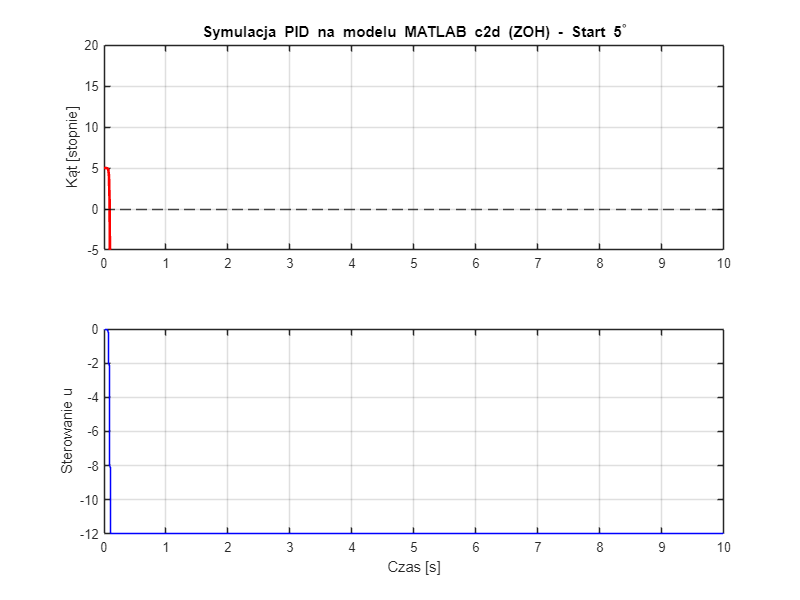


T_sim = 10;
N = T_sim / Ts;

y = zeros(1, N);
u = zeros(1, N);
e = zeros(1, N);

start_angle = deg2rad(5);
y(1:order+1) = start_angle;
e(1:order+1) = -start_angle;

max_u = 12;

for k = (order+2):N
    e(k) = 0 - y(k-1);
    
    u(k) = u(k-1) + r_0*e(k) + r_1*e(k-1) + r_2*e(k-2);
    
    if u(k) > max_u, u(k) = max_u; 
    elseif u(k) < -max_u, u(k) = -max_u; 
    end
    
    y_part = 0;
    u_part = 0;
    
    for i = 2:length(den)
        y_part = y_part - den(i) * y(k-(i-1));
    end
    for i = 2:length(num)
        u_part = u_part + num(i) * u(k-(i-1));
    end
    
    y(k) = (y_part + u_part) / den(1);
end

t_vec = 0:Ts:(N-1)*Ts;

figure('Position', [100, 100, 800, 600]);
subplot(2,1,1);
plot(t_vec, rad2deg(y), 'r-', 'LineWidth', 2);
grid on;
title(['Symulacja PID na modelu MATLAB c2d (ZOH) - Start 5^\circ']);
ylabel('Kąt [stopnie]');
yline(0, 'k--');
xlim([0, 10]);
ylim([-5, 20]);

subplot(2,1,2);
stairs(t_vec, u, 'b-');
grid on;
ylabel('Sterowanie u');
xlabel('Czas [s]');

% xlim([0, 3]);
% ylim([-12, 12]);